# 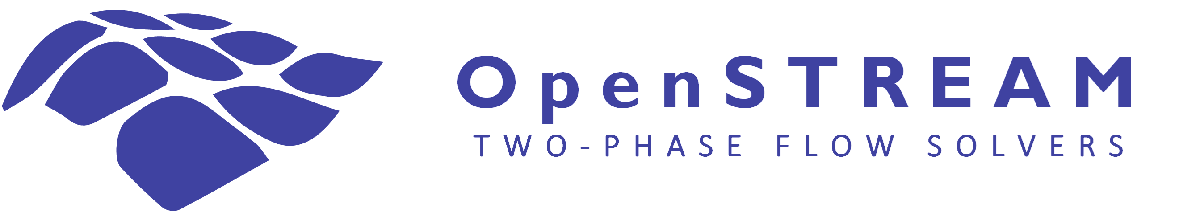

# Tutorial #3: Two-fluid solver capabilities

In this tutorial, you will explore capabilities specific to the OpenSTREAM two-fluid solver. The solver represents the liquid and vapor as separate fields and solves phase mass, momentum, and energy transport. This allows differences in phase mass flow rates, velocities, enthalpies, and temperatures, together with interfacial mass, momentum, and energy exchanges.

*Note: The flow-regime transitions and closure models currently implemented in the two-fluid solver are based on simplified assumptions. Consequently, some calculated results may not be physically realistic. Further development and validation of the flow-regime and closure models are required before the solver can provide reliable predictions across a broad range of conditions.*

The selected geometry consists of a 3.5 m uniformly heated vertical tube with an inner diameter of 8.8 mm, followed by a 2 m adiabatic section with the same diameter. The flow enters slightly subcooled and is progressively vaporized in the heated section.

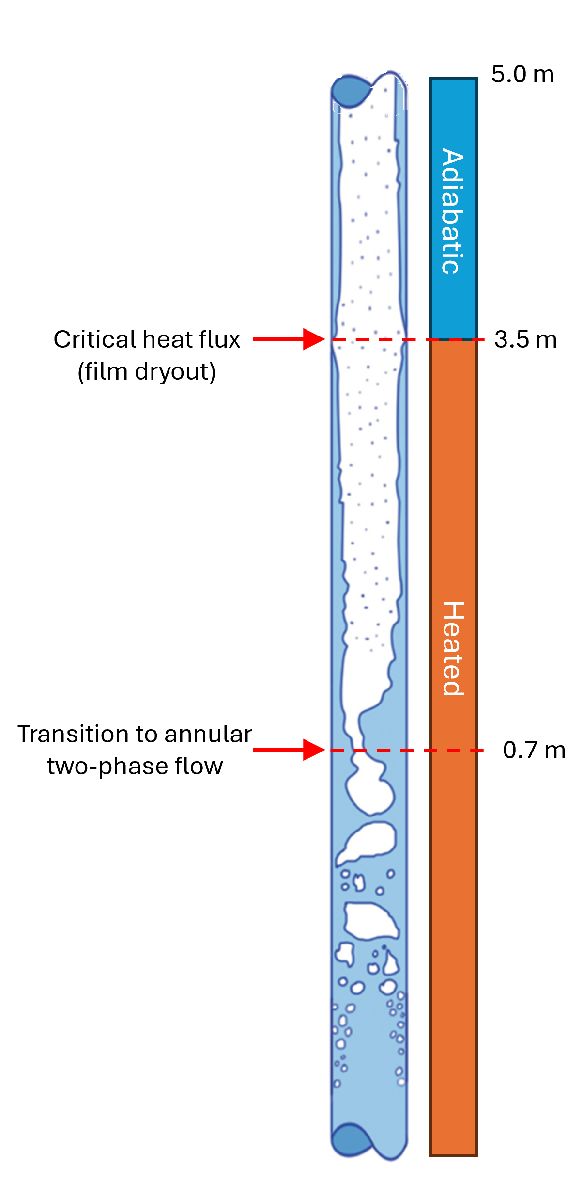

Learning objectives:

- Inspect and select the input sets used to configure two-fluid-solver calculations.

- Construct and run a default two-fluid calculation.

- Apply full phase momentum and energy conservation models.

- Examine hydrodynamic and thermal nonequilibrium between the liquid and vapor phases.

- Interpret interfacial-area distributions and flow-regime indicators.

- Analyze phase mass, momentum, and energy exchange terms.

- Visualize the pseudo-time convergence history of the phase fields.

- Perform and visualize a transient two-fluid calculation.

*Note: This tutorial is designed for use with output displayed inline (View > Output Inline) in the MATLAB Live Editor. Any animations are displayed in separate pop-up figure windows and can be played continuously or inspected one stored time step at a time. Animations and their controls are not preserved in static Markdown, HTML, or PDF exports.*

**Important**

*The physical models and closure relations selected in this tutorial are used for educational and demonstration purposes. Their use does not imply that they are appropriate, recommended, or validated for the simulated conditions. The calculated results should therefore be interpreted as illustrations of the solver framework and its capabilities, rather than as validated predictions. Before applying OpenSTREAM to a technical study, assess the assumptions, applicability range, and validation basis of every selected model.*

## Set up OpenSTREAM

Clear existing variables from the workspace.

clearvars

When this tutorial is run directly from the tutorials folder, the OpenSTREAM root directory is one level above the current folder.

osp = './..';
addpath(osp);

## Input files

All files required by this tutorial are provided in openstream/inputs.

Import the input, solver, mixture-solver, and two-fluid-solver packages.

import Inputs.*
import Solvers.*
import Solvers.Mixture.*
import Solvers.TwoFluid.*

Display the physical-model input file and locate the TUTORIAL3 entries.

type('../inputs/models.inp')

The following model sets are used:

- TUTORIAL3A specifies the axial discretization and working fluid. Other two-fluid model selections use their documented default values.

- TUTORIAL3B selects the RELAXATION interfacial heat-transfer treatment and FULL liquid- and gas-momentum conservation models.

Both sets use 100 axial nodes and water as the working fluid.

Display the numerical-option input file and locate the DEFAULT entry.

type('../inputs/options.inp')

No numerical options are specified for DEFAULT, so the calculation uses the documented default numerical settings.

 Display the geometry input file and locate the TUTORIAL1 entry.

type('../inputs/geom.inp')

Geometry inputs use SI units. The case represents a vertical upward flow in a circular tube with an inner diameter of 8.8 mm and a total length of 5.5 m.

Display the steady-state boundary-condition file.

type('../inputs/tutorial1.inp')

A single time entry defines a steady-state case. WMESH and WPOWER specify a 3.5 m uniformly heated section followed by a 2 m adiabatic section.

## Default two-fluid calculation

First create the input set for TUTORIAL3A. Warnings are temporarily suppressed to keep the tutorial output concise. During model development, leaving warnings enabled is recommended.

% Construct the input set.
warning off
inputSetA = InputSet( ...
    modelFilePath          = [osp '/inputs/models.inp'], ...
    modelID                = 'TUTORIAL3A', ...
    optionsFilePath        = [osp '/inputs/options.inp'], ...
    optionsID              = 'DEFAULT', ...
    geometryFilePath       = [osp '/inputs/geom.inp'], ...
    geometryID             = 'TUTORIAL1', ...
    bcFilePath             = [osp '/inputs/tutorial1.inp'], ...
    sessionParentDir       = fullfile(pwd,'outputs'), ...
    overwriteSessionFiles = true, ...
    LOGMODE                = 'BOTH');
warning on

The two-fluid solver requires a solved mixture solution for initialization and for the pressure-gradient calculation. If a mixture solver is not supplied, the constructor creates and solves one automatically.

% Create the two-fluid solver.
twfSolverA = TwoFluidSolver(inputSetA);

Inspect the initialized solver. The liquid and vapor fields are stored in separate objects, and the solved mixture solver is retained by the two-fluid solver.

disp(twfSolverA)
% Solve the two-fluid solver.
twfSolverA.solve();

At each pseudo-time step, the solver performs an axial sweep with local point iterations. It reports the maximum point-iteration count and the maximum iterative changes in the liquid and vapor mass flow rates, velocities, and enthalpies. Tutorial 7 explains the interpretation of pointwise and temporal convergence in greater detail.

% Plot the imposed and phase wall-heat-flux distributions.
twfSolverA.plotz('display','HFLUX','resize',1);
% Plot phase mass flow rates.
twfSolverA.plotz('display','W','resize',1);

The liquid and vapor mass flow rates show how mass is redistributed between the phases as wall evaporation and interfacial condensation occur.

% Plot phase velocities.
twfSolverA.plotz('display','U','resize',1);

For simplicity, the two-fluid solver uses the phase velocities obtained from the mixture-solver solution by default. Therefore, the separate liquid- and vapor-momentum conservation equations are not solved in this configuration. Because the default mixture models used in this case assume complete hydrodynamic coupling between the phases, the calculated liquid and vapor velocities are equal. The next case selects the FULL momentum model for both phases, allowing the liquid and vapor velocities to be calculated from their respective momentum conservation equations.

% Plot equilibrium quality, vapor mass quality, and void fraction.
twfSolverA.plotz('display','VR','resize',1);

These are distinct quantities: equilibrium quality is defined by the mixture thermodynamic state, vapor mass quality is based on the vapor mass flow rate, and void fraction is the vapor volumetric fraction.

% Save the solver object if desired.
twfSolverA.save('name','twfSolverA','showpath',false);

## Full phase momentum and energy calculation

TUTORIAL3B selects full liquid- and vapor-momentum conservation and a relaxation treatment for interfacial heat and mass transfer.

% Construct the input set.
warning off
inputSetB = InputSet( ...
    modelFilePath          = [osp '/inputs/models.inp'], ...
    modelID                = 'TUTORIAL3B', ...
    optionsFilePath        = [osp '/inputs/options.inp'], ...
    optionsID              = 'DEFAULT', ...
    geometryFilePath       = [osp '/inputs/geom.inp'], ...
    geometryID             = 'TUTORIAL1', ...
    bcFilePath             = [osp '/inputs/tutorial1.inp'], ...
    sessionParentDir       = fullfile(pwd,'outputs'), ...
    overwriteSessionFiles = true, ...
    LOGMODE                = 'BOTH');
warning on

Create the mixture solver explicitly so that its solution can be examined and reused. Passing the solved object prevents the two-fluid constructor from repeating the mixture calculation.

% Create and solve the mixture solver.
mixSolverB = MixtureSolver(inputSetB);
mixSolverB.solve();
% Create and solve the two-fluid solver.
twfSolverB = TwoFluidSolver(inputSetB, mixSolverB);
twfSolverB.solve();

### Hydrodynamic nonequilibrium

Compare mixture and phase mass flow rates and velocities.

twfSolverB.plotz( ...
    'display', {'W','U'}, ...
    'arrangement', 'horizontal', ...
    'resize', 1);

The mixture solution supplies the total-flow initialization and pressure gradient. The two-fluid solver then calculates separate liquid and vapor mass, momentum, and energy balances.

The full momentum formulations allow the phase velocities to differ. The resulting slip reflects the modeled balance of wall, interfacial, gravitational, buoyancy, and phase-change momentum exchanges.

### Thermal nonequilibrium

Plot the phase enthalpies relative to saturated-liquid and saturated-vapor enthalpies.

twfSolverB.plotz('display','H','resize',1);

Plot liquid, vapor, and saturation temperatures in degrees Celsius.

twfSolverB.plotz( ...
    'display', 'T', ...
    'unitTemp', 'C', ...
    'resize', 1);

Differences between phase temperatures and saturation temperature show the thermal nonequilibrium calculated by the selected models.

Plot qualities and void fraction.

twfSolverB.plotz('display','VR','resize',1);

### Interfacial area and flow-regime indicators

Plot the volumetric interfacial area used by the interfacial transfer models.

twfSolverB.plotz('display','INTAREA','resize',1);

Plot the flow-regime classification stored by the liquid field.

twfSolverB.plotz('display','REGIME','resize',1);

These plots help connect the local phase state to the closure quantities used for interfacial mass, momentum, and energy transfer.

### Phase mass exchanges

Plot the vapor and liquid mass-exchange contributions.

twfSolverB.plotz( ...
    'display', 'PWE', ...
    'arrangement', 'horizontal', ...
    'resize', 1);

The available contributions include wall evaporation, interfacial evaporation, interfacial condensation, and the total phase mass exchange.

The liquid and vapor totals should be interpreted with their phase sign convention.

### Phase momentum exchanges

Plot the phase momentum-exchange contributions.

twfSolverB.plotz( ...
    'display', 'PME', ...
    'arrangement', 'horizontal', ...
    'resize', 1);

The plotted terms include wall shear, interfacial shear, buoyancy, gravity, and momentum associated with phase change, as applicable to each phase.

### Phase energy exchanges

Plot the phase energy-exchange contributions.

twfSolverB.plotz( ...
    'display', 'PEE', ...
    'arrangement', 'horizontal', ...
    'resize', 1);

The plotted terms include wall heating and energy transfer associated with wall evaporation, interfacial evaporation, and interfacial condensation, together with the total energy exchange for each phase.

### Pseudo-time convergence history

The liquidInit and vaporInit arrays store the pseudo-time iterations used to obtain the initial steady-state solution. The NULL solve mode plots that convergence history rather than the physical transient solution.

twfSolverB.plotz( ...
    [], ...
    'display', {'W','U','H'}, ...
    'solveMode', 'NULL', ...
    'resize', 1);

Plot the pseudo-time history at the outlet.

twfSolverB.plott( ...
    twfSolverB.NZ, ...
    'display', {'W','U','H'}, ...
    'solveMode', 'NULL', ...
    'resize', 1);

This view is useful for examining how the phase solution approaches the final steady state and for identifying the variables that control the convergence rate.

## Physical transient calculation

The transient boundary-condition file specifies a reduction in power. Display the file before constructing the transient case.

type('../inputs/tutorial2_transient.inp')

Use the TUTORIAL3B two-fluid model selections with the transient boundary conditions.

% Construct the input set.
warning off
inputSetC = InputSet( ...
    modelFilePath          = [osp '/inputs/models.inp'], ...
    modelID                = 'TUTORIAL3B', ...
    optionsFilePath        = [osp '/inputs/options.inp'], ...
    optionsID              = 'DEFAULT', ...
    geometryFilePath       = [osp '/inputs/geom.inp'], ...
    geometryID             = 'TUTORIAL1', ...
    bcFilePath             = [osp '/inputs/tutorial2_transient.inp'], ...
    sessionParentDir       = fullfile(pwd,'outputs'), ...
    overwriteSessionFiles = true, ...
    LOGMODE                = 'BOTH');
warning on

% Create the two-fluid solver.
twfSolverC = TwoFluidSolver(inputSetC);

The constructor automatically creates and solves the corresponding transient mixture solver, which supplies the initial state and pressure gradient for every physical time step.

% Solve the two-fluid solver.
twfSolverC.solve();

Plot selected axial distributions for all stored physical times. Multiple time indices produce an animated axial plot.

twfSolverC.plotz( ...
    [], ...
    'display', {'HFLUX','W','T','VR'}, ...
    'unitTemp', 'C', ...
    'resize', 1);

Plot the physical-time response at the channel outlet.

twfSolverC.plott( ...
    twfSolverC.NZ, ...
    'display', {'HFLUX','W','T','VR'}, ...
    'unitTemp', 'C', ...
    'resize', 1);

The axial animation shows the spatial evolution of the solution, while the outlet time histories show the local response to the imposed power transient.

## Summary

In this tutorial, you initialized and solved the two-fluid model, examined separate phase mass, momentum, and energy variables, visualized closure quantities and phase-exchange terms, inspected pseudo-time convergence, and calculated a physical transient.